load letterDatasetClass.mat;
letterDataset = letterDatasetStandardised;
rng(10);
[x, y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
 

Grow a weak tree ensemble of 50 trees

model = TreeBagger(50, x, y, "OOBPrediction", "On", ...
  "method", "classification");


Plot the out of bag classification over the number of grown trees

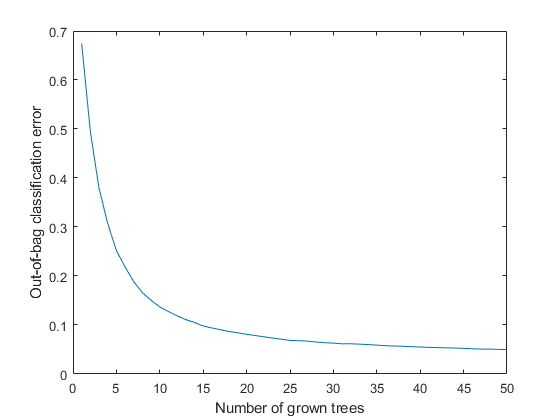

figure;
oobErrorBaggedEnsemble = oobError(model);
plot(oobErrorBaggedEnsemble)
xlabel 'Number of grown trees';
ylabel 'Out-of-bag classification error';